## **Basis:**

simplified model:

front spar + rear spar + skin.

Separate the loading into a force on shear centre(flexural axis) and a torque

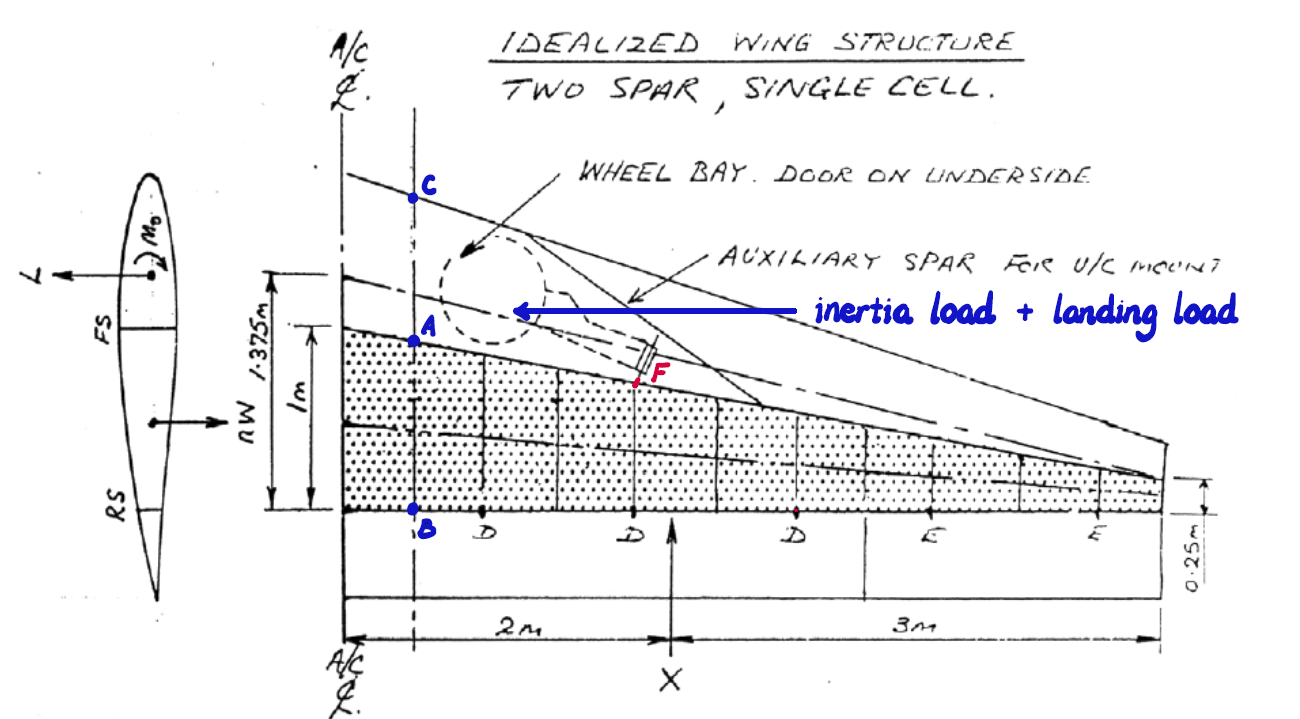

actual model:

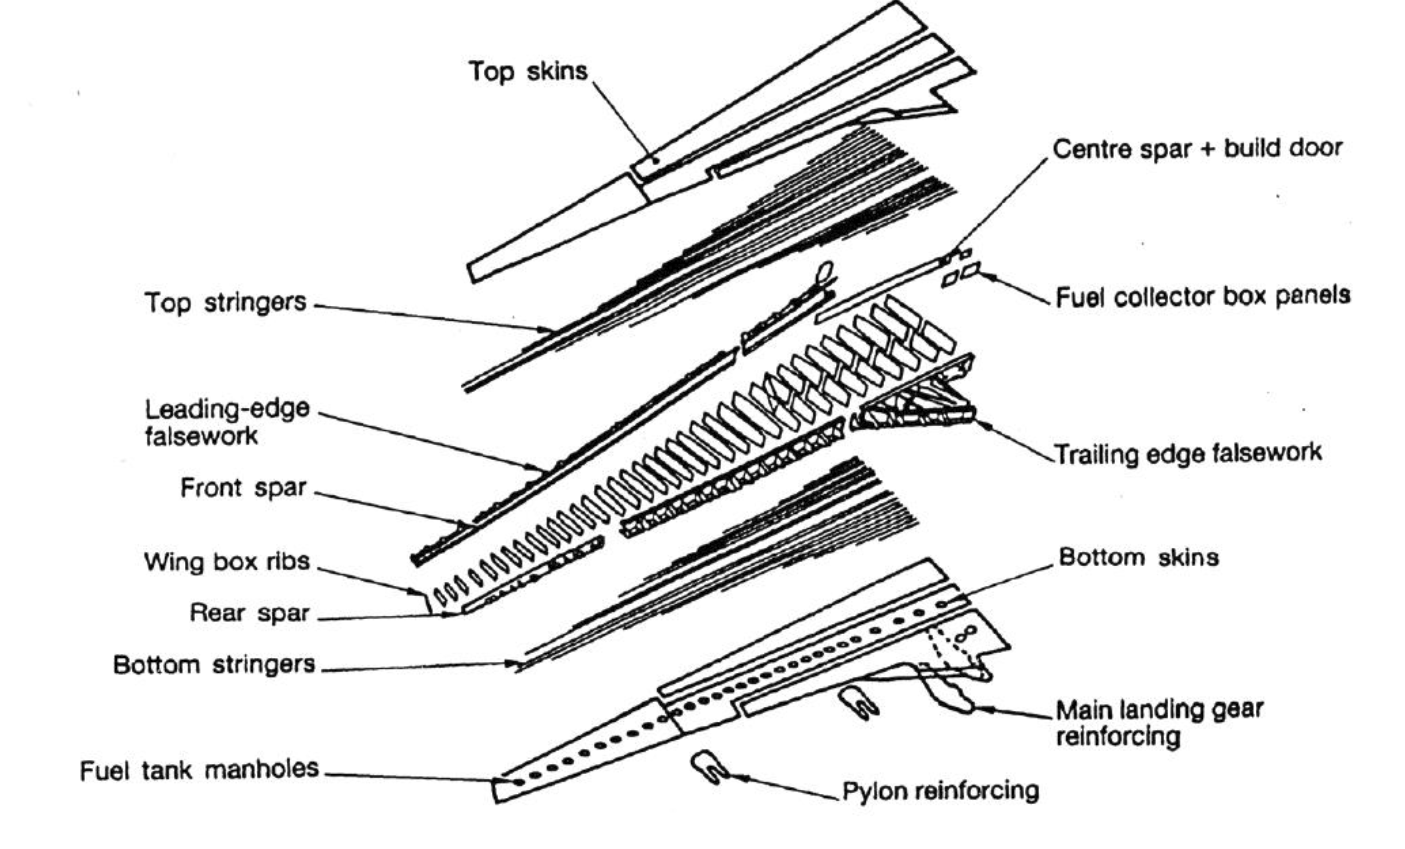

Top surface is under compression, more stringers

Bottom surface is under tension, less stringers

-skin thickness and number of ribs are inversely proportional

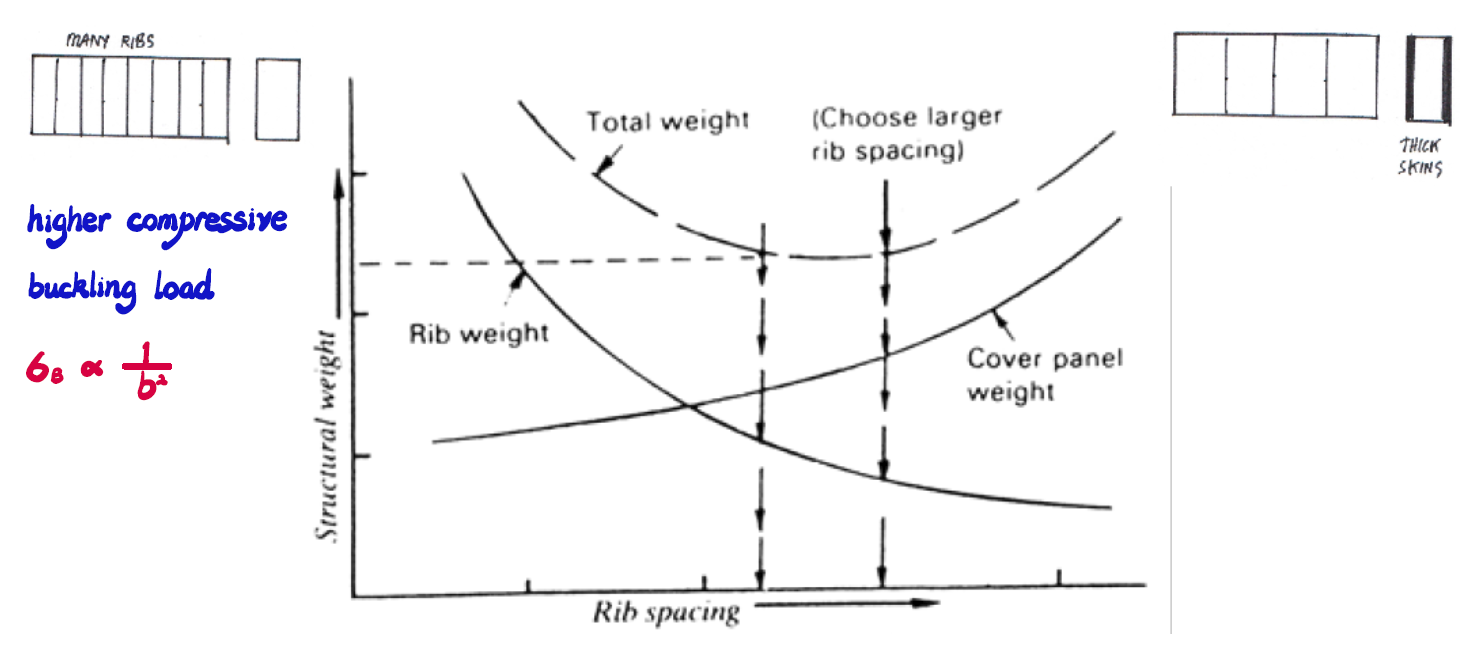

Web:

sine-wave web for composite

metal:

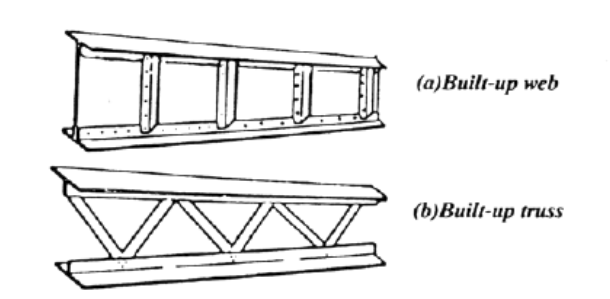

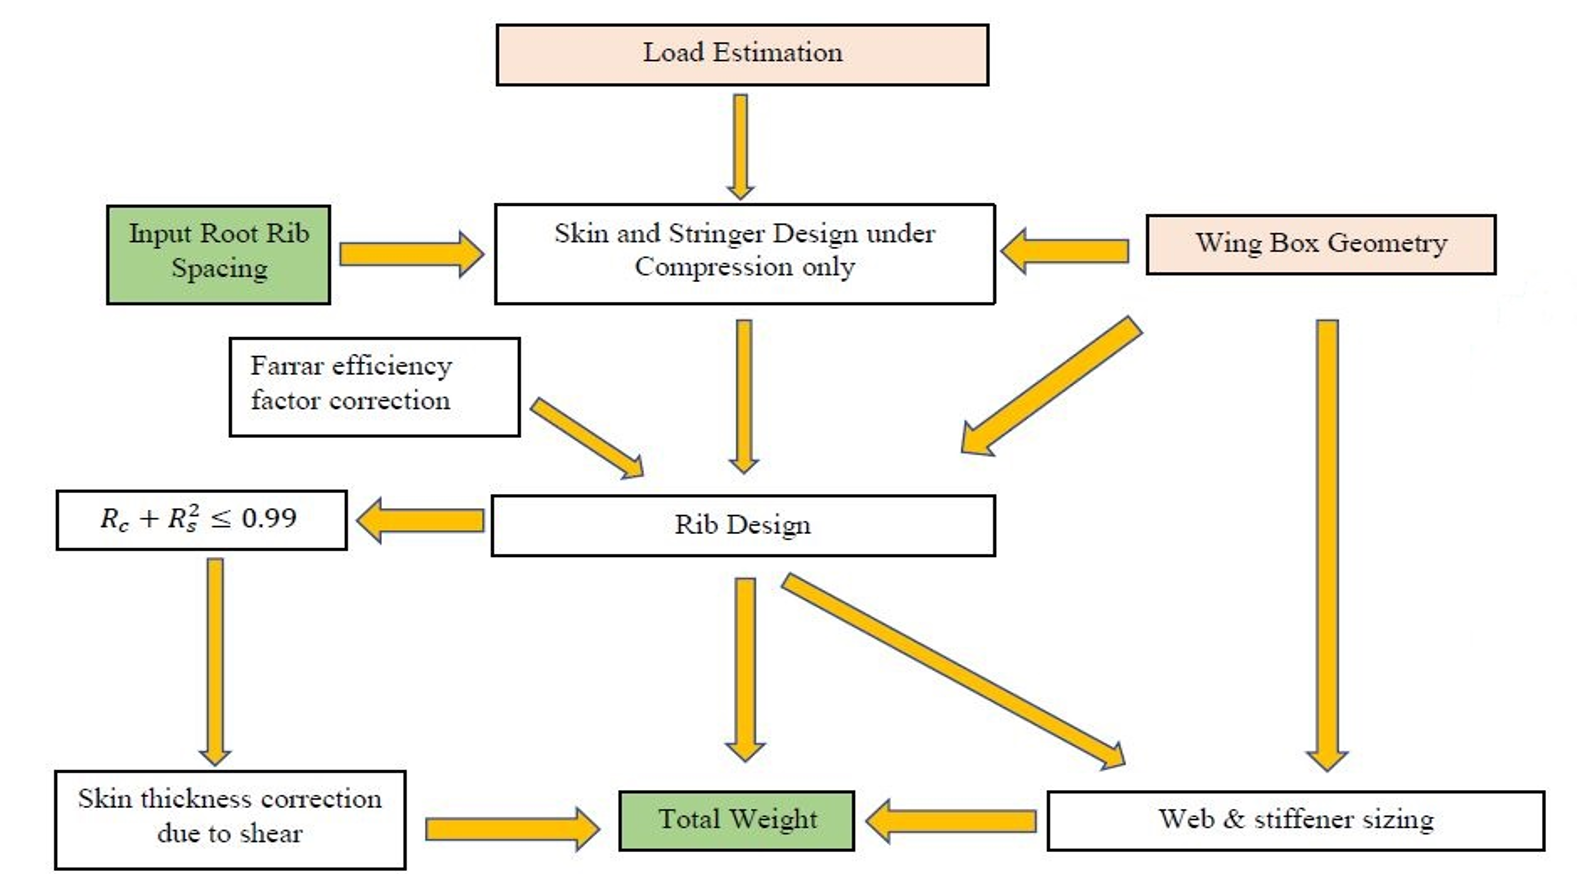

## 1.skin design

sigmacr/sigma0 is from** catchpole diagram**

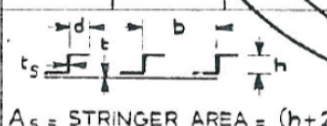

load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
T = readtable("E - Wing Load.xlsx",'Sheet',"Wing Torque");

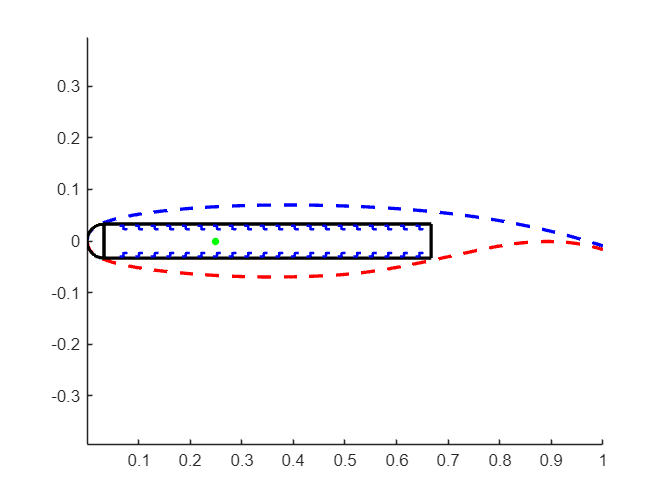

location = table2array(T(1:60,3));
M = table2array(T(1:60,25))*1e-3;

steel=material();
steel.E = 70e9;

wb = wingbox();
%define geometry
wb.c_c = 0.634;
wb.b2_c = 0.066;
wb.R1_c = wb.b2_c/2;
wb.R2_c = wb.R1_c;
%define stringers
wb.N = 20;
wb = wb.calcb1();
wb.ts = 10e-3;
wb.hs = 80e-3;
wb.ds = wb.hs*0.3;
wb = wb.calcStringerArea();
wb.t2 = 7.72e-3;
wb.L = 1;


figure(1)
clf;
wb.drawwithAirfoil(airfoil)


display("ts/t2:")

    "ts/t2:"



display(wb.ts/wb.t2)

    1.2953



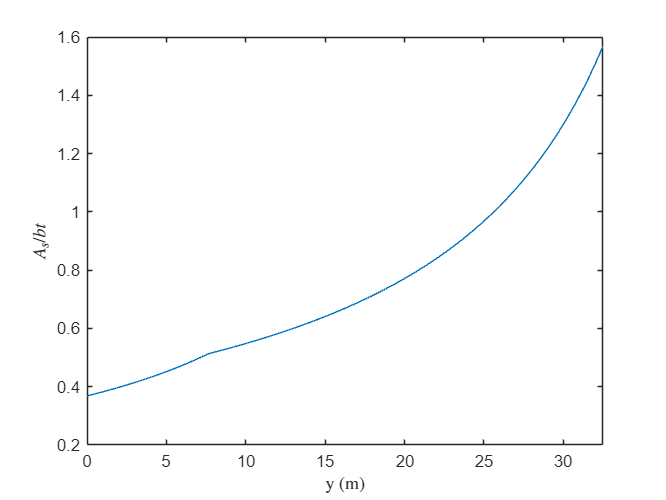


figure(2)
clf;
plot(wing_opt.stripy, wb.As./(wb.b1_c.*wing_opt.cn)./wb.t2)
xlabel("y (m)","Interpreter","latex")
ylabel("$A_s/bt$","Interpreter","latex")
xlim([0 wing_opt.s])

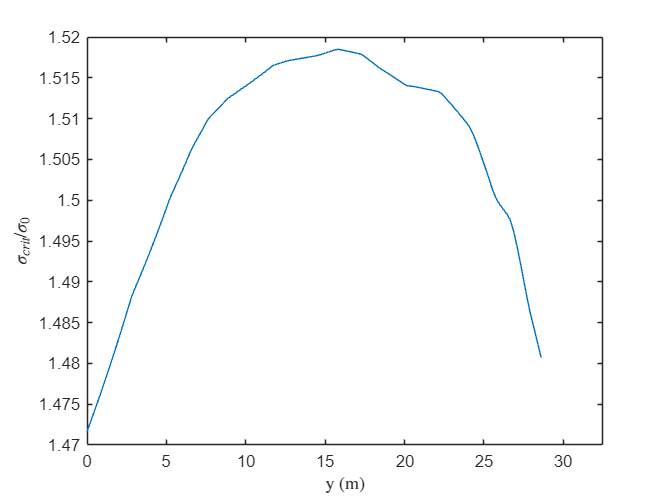

wb = wb.interpsr_s0(digitized_data,wing_opt);
figure(3)
plot(wing_opt.stripy, wb.sr_s0)
xlim([0 wing_opt.s])
xlabel("y (m)","Interpreter","latex")
ylabel("$\sigma_{crit}/\sigma_{0}$","Interpreter","latex")

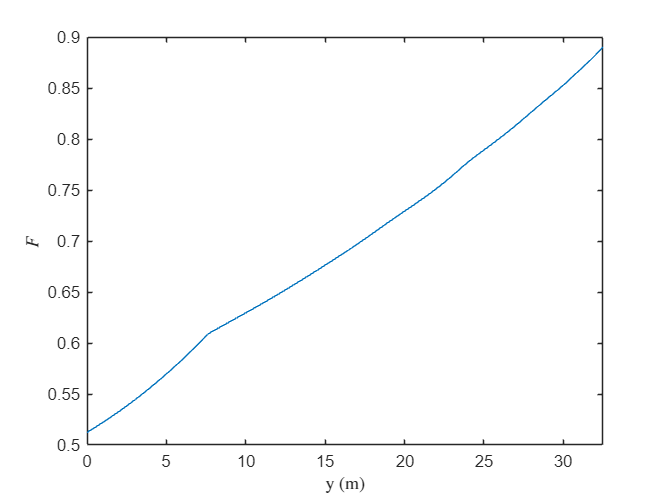


wb = wb.interpretF(F_data, wing_opt);
figure(4)
clf;
plot(wing_opt.stripy, wb.F)
xlim([0 wing_opt.s])
xlabel("y (m)","Interpreter","latex")
ylabel("$F$","Interpreter","latex")


figure(5)
clf;
location = location + 3.2

location =     3.2000
    3.7000
    4.2000
    4.7000
    5.2000
    5.7000
    6.2000
    6.7000
    7.2000
    7.7000



location_full = [-flip(location);location];
M_full = [flip(M);M];
plot(location_full,M_full)
M_new = interp1(location_full, M_full, wing_opt.stripy, 'spline');
hold on
M = M_new

M = 1.0e+04 *

         0    0.0003    0.0018    0.0045    0.0083    0.0131    0.0188    0.0251    0.0319    0.0392    0.0469    0.0552    0.0638    0.0728    0.0822    0.0920    0.1021    0.1126    0.1233    0.1344    0.1458    0.1574    0.1694    0.1816    0.1941    0.2068    0.2198    0.2330    0.2465    0.2602    0.2741    0.2883    0.3027    0.3172    0.3320    0.3470    0.3622    0.3776    0.3932    0.4090    0.4249    0.4411    0.4574    0.4739    0.4906    0.5074    0.5244    0.5415    0.5589    0.5765


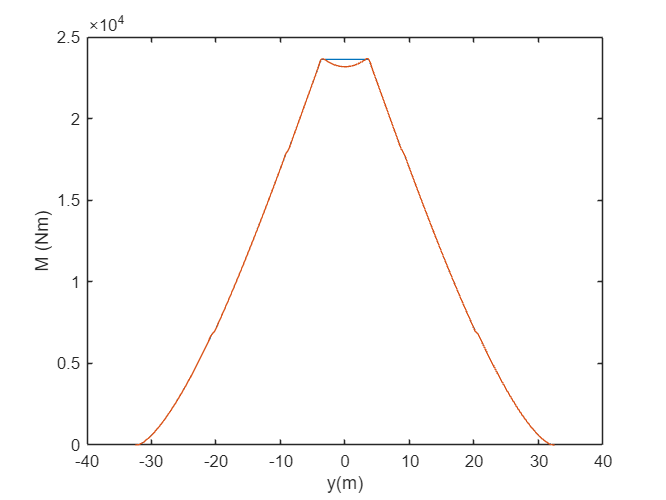

plot(wing_opt.stripy,M)
xlabel("y(m)")
ylabel("M (Nm)")


%critical stress: Euler buckling
%Farror: Local buckling
%They should happen at the same time(optimized) i.e. sigma_cr - sigma_f = 0
sigma_cr = findCricStress(wb,M,wing_opt,steel)

sigma_cr = 1.0e+08 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    2.3952    2.3343    2.2758    2.2194    2.1655    2.1140    2.0644    2.0164    1.9698    1.9243    1.8795    1.8362    1.7943    1.7539    1.7154    1.6784    1.6426    1.6079    1.5743    1.5417    1.5100    1.4791    1.4489    1.4196    1.3912    1.3636    1.3368    1.3109    1.2856    1.2611    1.2371    1.2137


sigma_f = findFStress(wb,M,wing_opt,steel)

sigma_f = 1.0e+07 *

         0    0.0579    0.1341    0.2060    0.2748    0.3394    0.3982    0.4507    0.4982    0.5418    0.5821    0.6194    0.6540    0.6862    0.7164    0.7446    0.7710    0.7957    0.8188    0.8404    0.8607    0.8797    0.8976    0.9144    0.9301    0.9450    0.9590    0.9722    0.9847    0.9965    1.0076    1.0180    1.0279    1.0373    1.0460    1.0543    1.0620    1.0692    1.0759    1.0820    1.0875    1.0925    1.0968    1.1007    1.1045    1.1080    1.1113    1.1143    1.1173    1.1200


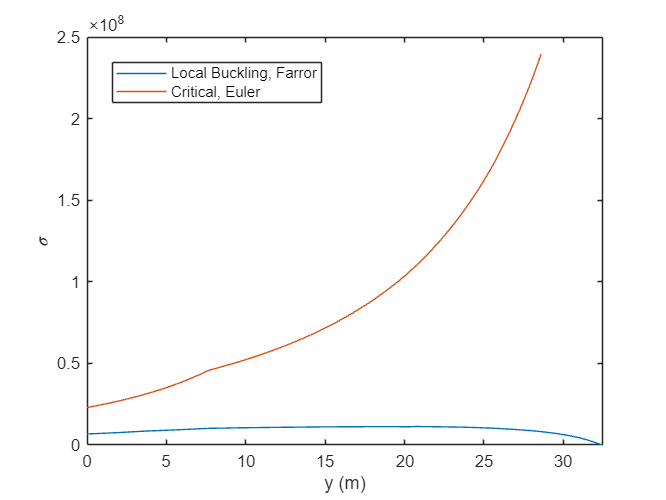

figure(6)
clf;
plot(wing_opt.stripy, sigma_f);
hold on
plot(wing_opt.stripy, sigma_cr);
legend("Local Buckling, Farror","Critical, Euler")
xlabel("y (m)")
ylabel("$\sigma$","Interpreter","latex")
xlim([0 wing_opt.s])